clear
load YaleB_32x32.mat
rng(1)
%Extract LBP features
LBP_matrix = zeros(2414,59);
for f = 1:size(fea,1)
    A = fea(f,:);
    A = reshape(A,[32,32]);
    img = mat2gray(A);
    lbp = extractLBPFeatures(img);
    LBP_matrix(f,:) = lbp;
end

Combine the LBP Matrix with gnd

YaleB = [LBP_matrix, gnd];
m = 30;
k = 3; 
K = 38;
%Set up training set and testing set data
train_50 = [];
test_50 = [];
for i = 1:K
    G = YaleB(YaleB(:,60) == i, 1:60); % extract data of class i
    idx = randperm(size(G,1),m); %randomly generate m integers 1 to size(G,1)
    vec = [1: size(G,1)]; % Need this to extract test set

    test_idx = setdiff(vec,idx);

    test_set = G(test_idx,:);
    test_50 = [test_50; test_set];

    train = G(idx,:);
    train_50 = [train_50;train];
end

X_train = train_50(:,1:59);
Y_train = train_50(:,60);
X_test = test_50(:,1:59);
Y_test = test_50(:,60);   

Calculate Error for LBP

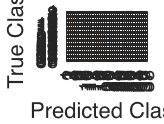

Error_LBP = [0,0];
p_list = [1,2];

for p = p_list
    %train 3NN
    model_p = fitcknn(X_train, Y_train, 'Distance', 'minkowski', 'NumNeighbors', 3);
    model_p.DistParameter = p;
    predict_y_test = predict(model_p, X_test);

    error_vec = predict_y_test ~= Y_test;
    Error_p = (sum(error_vec) / size(Y_test,1)) * 100;
    Error_LBP(p) = Error_p;
end
C = confusionmat(Y_test, predict_y_test); % known vs predict
confusionchart(C)